# ASR iteration to identify bad channels and samples

av_20210607

function [EEG] = cmi_preproc_land_iteration(EEG, cfg, subid, sub_idx, dataType)

*-> if I well understood "sub_idx" is a counter and "subid" is the string with the subject name: *

*  so maybe we can replace "subid" with "sub_name"  ??*

% 
% CMI_PREPROC_LAND preprocess CMI data with LAND preprocessing pipeline
%   

%% load dataset
if ~exist('EEG')    
    eeg_struct = pop_loadset('filename',cfg.setfilename{sub_idx,1});
    eeg_raw = eeg_struct;
else
    eeg_struct = EEG;
    eeg_raw = eeg_struct;
end % if ~exist('EEG')

%% SOME CHECKS - - - - - -
sample_rate = eeg_struct.srate;
% length in sec of the recording:
n_sample = eeg_struct.pnts;
n_sample / sample_rate;  %in sec
n_chan = eeg_struct.nbchan;

% number of channel that can be retained for ICA
%(number of channel)^2 x 20 to 30 data points to perform ICA
if n_sample > n_chan^2 * 20
    disp([ num2str ' channels can be given as input to ICA'])
else
    n_chan_max = sqrt(n_sample/20);
    disp([ 'number of channels for ICA should be reduced to ' num2str(n_chan_max)])
end


%% Subset of 11 CHANNELS as EOG - - - - - - - - - - - - - -
chan_eye = {'E128', 'E32', 'E25', 'E21', 'E127', 'E17',...
    'E126', 'E14', 'E8', 'E1', 'E125'}

eye_struct = pop_select(eeg_struct, 'channel', chan_eye);


%% 26 CHANNELs to be REMOVED
fprintf('... REMOVING CHANNELS \n')

chan_toreject = cfg.pp.chan_toreject;

eeg_struct = pop_select(eeg_struct, 'nochannel', chan_toreject);
eeg_raw_chanred = eeg_struct;

%% DOWNSAMPLE
fprintf('... DOWNSAMPLING \n')
eeg_struct = pop_resample(eeg_struct, cfg.pp.downsample_rate);
% fix latency so they are integers
for i = 1:length(eeg_struct.event)
    eeg_struct.event(i).latency = ceil(eeg_struct.event(i).latency); 
end % for i
eeg_down = eeg_struct;


%% BAND-PASS FILTERED data
fprintf('... BAND-PASS FILTERING \n')

eeg_struct = pop_eegfiltnew(eeg_struct, cfg.pp.hpf_cutoff, [], [],0,[],0);
eeg_hpf = eeg_struct;

eeg_struct = pop_eegfiltnew(eeg_struct, [], cfg.pp.lpf_cutoff, [],0,[],0);
eeg_lpf = eeg_struct;


%% cleanraw data + Artifact Subspace Reconstruction + avgref + ICA
% https://github.com/sccn/clean_rawdata/wiki
%
%
% ASR == good at removing occasional large-amplitude noise/artifacts
% ICA == good at decomposing constant fixed-source noise/artifacts/signals
%
% vis_artifacts to compare the cleaned data to the original.
% ----------------------------------------------------------------

%   chancorr_crit                       - Correlation threshold. If a channel is correlated at less than this value
%                                           to its robust estimate (based on other channels), it is considered abnormal in
%                                           the given time window. OPTIONAL, default = 0.8.
%   chan_max_broken_time                - Maximum time (either in seconds or as fraction of the recording) during which a
%                                           retained channel may be broken. Reasonable range: 0.1 (very aggressive) to 0.6
%                                           (very lax). OPTIONAL, default = 0.5.
%   chan_detect_num_iter                - Number of iterations the bad channel detection should run (default = 10)
%   chan_detected_fraction_threshold	- Fraction how often a channel has to be detected to be rejected in the final
%                                           rejection (default 0.5)
%   flatline_crit                       - Maximum duration a channel can be flat in seconds (default 'off')

if cfg.pp.do_cleanraw
    
    close all; % close all figures
    
    %----------------------------------------------------------------------
    % LINE NOISE REMOVAL WITH NOTCH FILTER (instead of CLEANLINE)
    fprintf('... removing line noise with notch filter \n')
    eeg_notch = pop_eegfiltnew(eeg_struct, ...
        'locutoff',cfg.pp.line_noise_freq-2, ...
        'hicutoff',cfg.pp.line_noise_freq+2, ...
        'revfilt',1,'plotfreqz',1);
    
    
    %----------------------------------------------------------------------
    % ITERATION of BAD CHANNEL AND SAMPLE DETECTION
    %----------------------------------------------------------------------
    n_iter = 5; % seems quite stable so 5 iteration should be enough
    for i_iter = 1:n_iter
        fprintf('... do CLEANRAW iteration on NOTCH filtered data \n')
        [eeg_cleanraw_iter, HP, BUR, bad_chan_cleanraw] = clean_artifacts(eeg_notch, ...
            'ChannelCriterion',0.8, ...
            'LineNoiseCriterion',4, ...
            'FlatlineCriterion',5, ...
            'BurstCriterion',20, ...
            'WindowCriterion','off', ...
            'Highpass','off', ...
            'BurstRejection','on');  % <<< only for the purpose of identifying bad samples <<<<<<
               
        %vis_artifacts(eeg_cleanraw_iter,eeg_notch)
             
        % 0 means NO BAD channel/sample;  1 means BAD channel samples
        % (if some -1 value remains in the table.... something wrong !!
        bad_chan_table(i_iter,:) = ~eeg_cleanraw_iter.etc.clean_channel_mask;
        bad_sample_table(i_iter,:) = ~eeg_cleanraw_iter.etc.clean_sample_mask;
    end
    fprintf('!!! CLEANRAW iteration done .... \n')
    bad_chan_idx = find(sum(bad_chan_table,1) > 7);  % bad channel identified in more than 7 iteration
    bad_sample_idx = find(sum(bad_sample_table,1) > 7);  % bad channel identified in more than 7 iteration
    bad_sample_perc = sum(bad_sample_table,2) ./ eeg_notch.pnts *100
        
    % - - - - - - - - - - - - -  - -- -  -- - - -
    % final ATTEMPT TO REPAIR the BAD SAMPLEs:
    [eeg_cleanraw, HP, BUR, bad_chan_cleanraw] = clean_artifacts(eeg_notch, ...
        'ChannelCriterion',0.8, ...
        'LineNoiseCriterion',4, ...
        'FlatlineCriterion',5, ...
        'BurstCriterion',20, ...
        'WindowCriterion','off', ...
        'Highpass','off', ...
        'BurstRejection','off');  % <<<<<< repair and not removal <<<<<<<<<<<<
    fprintf('!!! CLEANRAW data done .... \n')

    % use vis_artifact to look at the difference between clean and raw data
    %vis_artifacts(eeg_cleanraw,eeg_notch)
    %vis_artifacts(eeg_cleanraw_iter,eeg_cleanraw)
    %vis_artifacts(eeg_cleanraw_iter,eeg_cleanraw_badchan_interp)
    
    %bad_chan_cleanraw = eeg_cleanraw.etc.clean_channel_mask;
    bad_chan_label = {};
    xx = 1;
    for i_chan = 1:length(eeg_cleanraw.etc.clean_channel_mask)
        if ~eeg_cleanraw.etc.clean_channel_mask(i_chan)
            bad_chan_label{1,xx} = eeg_notch.chanlocs(i_chan).labels;
            xx = xx+1;
        end
    end
        
    % - - - - - - - - - -
    % CHECK which portion of the data is still considered as artifactual (even after ASR)
    [eeg_cleanraw_ASR2, HP, BUR, bad_chan_cleanraw] = clean_artifacts(eeg_cleanraw, ...
        'ChannelCriterion',0.8, ...
        'LineNoiseCriterion',4, ...
        'FlatlineCriterion',5, ...
        'BurstCriterion',20, ...
        'WindowCriterion','off', ...
        'Highpass','off', ...
        'BurstRejection','on');  %
    fprintf('!!! CLEANRAW + second run of ASR done .... \n')

    % some PLOTs = = =  = = = = = = = = = =
    if do_save_fig
        
        %color_lim = [ 1 n_iter ];
        figure; set(gcf,'position',[10,10,1800,1000])
        subplot(231)
        imagesc(bad_chan_table')
        xlabel('iteration'); ylabel('CHANNEL')
        %caxis(color_lim)
        title([' n° BAD CHAN = ' num2str(length(bad_chan_idx))])
        
        %subplot(234); topoplot( ~eeg_cleanraw_iter.etc.clean_channel_mask, eeg_cleanraw.chanlocs, ...
        subplot(234); topoplot( sum(bad_chan_table,1), eeg_notch.chanlocs, ...
            'electrodes','labelpoint','chaninfo',eeg_notch.chaninfo) ;
        %colormap(gca,'gray')
        title(bad_chan_label)
        
        subplot(2,3,2:3)
        imagesc(bad_sample_table)
        ylabel('iteration'); xlabel('(BAD) SAMPLE  (10k samples = 40 sec)')
        title([' % of BAD SAMPLE = ' num2str(mean(bad_sample_perc))])
        
        % AFTER second round of ASR
        bad_sample_ASR2_table = double(~eeg_cleanraw_ASR2.etc.clean_sample_mask);
        subplot(3,3,8:9)
        %         plot(sum(bad_sample_table,1));
        %         xlim([1 eeg_notch.pnts])
        %         ylabel({'n iteration';'where a sample is identified as BAD'})
        imagesc(bad_sample_ASR2_table);
        colormap(gca,'gray')
        title('BAD segment  after initial ASR repair')
        
        cd(save_dir)
        save_name = [ subj_name '_' file_set(1:end-4) '_bad_sample&channel.jpg']
        saveas(gcf, save_name)
    end
    
    

figure example

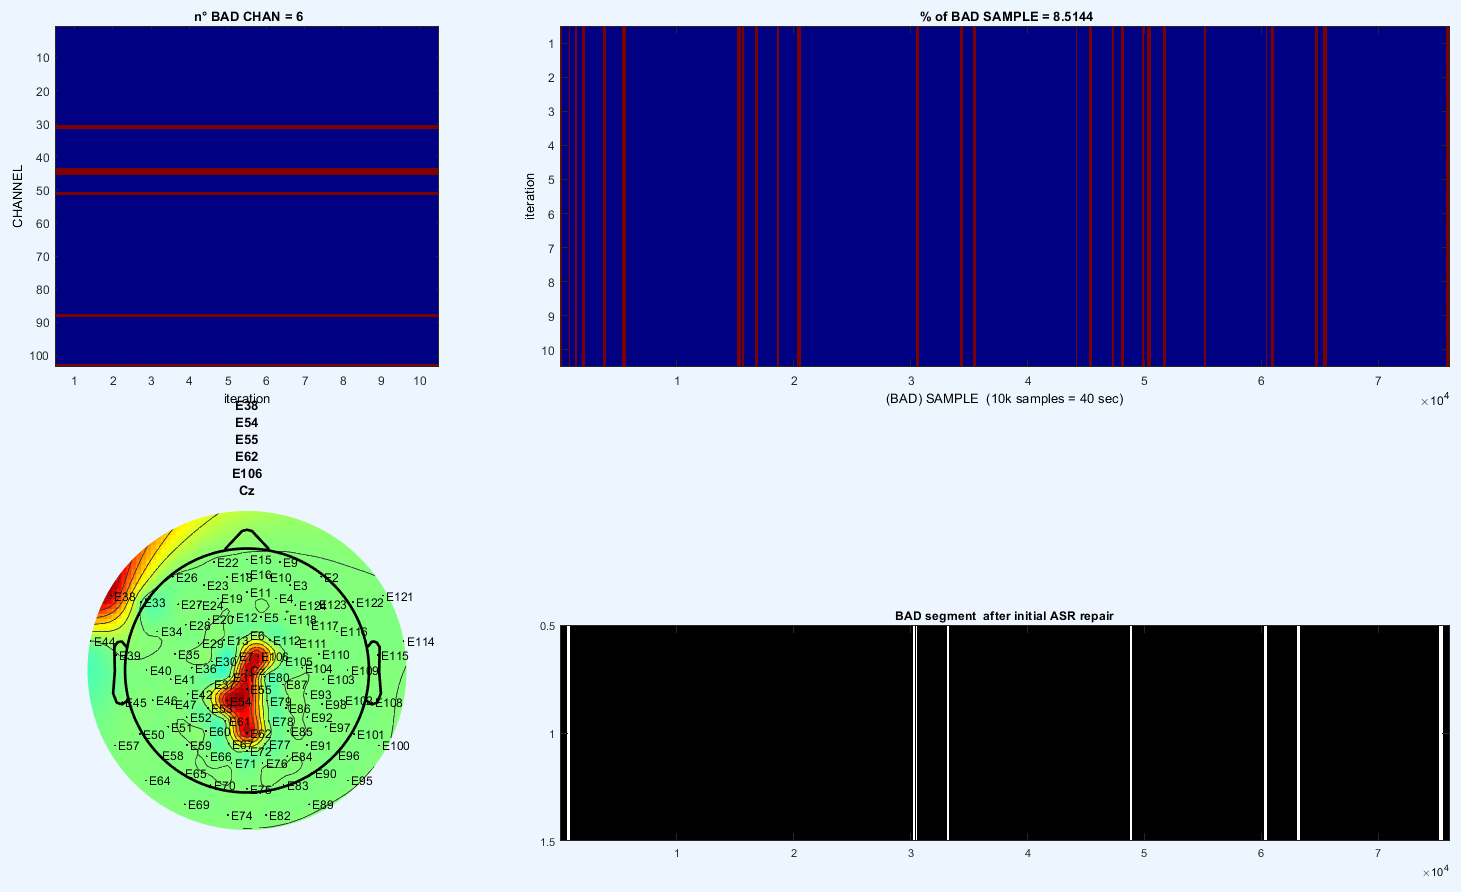

            
    % = = = = = = = = = = = = = = = = = = = = = =
    % INTERPOLATE (before ICA ??) using also the channels to be pruned in the next step
    fprintf('... channel interpolation \n')
    eeg_cleanraw_badchan_interp = pop_interp(eeg_cleanraw, eeg_struct.chanlocs, 'spherical');
    % !!! also Cz is interpolated
    
    % !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
    % disp('The function clean_rawdata has been deprecated and is only kept for backward compatibility');
    % disp('Use the clean_artifacts function instead.');
    
    % !!! for setting the appropriate parameters of the function see this paper:
    % https://pubmed.ncbi.nlm.nih.gov/31329105/
    % (see also: Comments to the HAPPE paper, and how to choose the critical parameters
    
    
    %  RE-REFERENCE to the AVERAGE
    eeg_cleanraw_avgref = pop_reref(eeg_cleanraw_badchan_interp, []);
    %eeg_avgref = eeg_struct;
        
    %----------------------------------------------------------------------
    % further CHAN REDUCTION x ICA ??
    fprintf('... channel reduction before ICA \n')
    % pop_chanedit(eeg_cleanraw_avgref)
    % pop_eegbrowser(eeg_cleanraw_avgref)
    chan_interp_prune = cfg.pp.chan_interp_prune;
    
    eeg_cleanraw_avgref = pop_select(eeg_cleanraw_avgref, 'nochannel', chan_interp_prune);
    
    %----------------------------------------------------------------------
    % ICA DECOMPOSITION (classification and rejection)
    fprintf('... running ICA \n')
    eeg_cleanraw_avgref_ICA = pop_runica(eeg_cleanraw_avgref, 'icatype', 'runica', 'extended',1,'interrupt','on');
    
    % (PLOT component topography:)
    % (see: https://github.com/sccn/viewprops)
    % pop_topoplot(eeg_ICA, 0, [1:length(chan_toinclude)] ,'EDF file',[5 5] ,0,'electrodes','on');
    
    % !!! to notice: according to KLUG, GRAMANN 2020:
    % 'default' classifier did not lead to good classification of muscular artifact, 'lite' was better overall.
    eeg_cleanraw_avgref_ICA = pop_iclabel(eeg_cleanraw_avgref_ICA, 'default');
    
    % for component viewing
    if cfg.pp.do_save_cleanraw_avgref_ICA
        fname2save = fullfile(cfg.preproc_data_dir, subid, dataType, sprintf('%s_%s_cleanraw_avgref_ICA.set',subid,dataType));
        pop_saveset(eeg_cleanraw_avgref_ICA, 'filename', fname2save)
    end % if cfg.pp.do_save_cleanraw_avgref_ICA

    %----------------------------------------------------------------------
    % REMOVE BAD COMPONENT based on ICLabels
    fprintf('... removing bad components with IClabels \n')
    %eeg_nobadICA = pop_icflag(eeg_ICA, [NaN NaN;0.8 1;0.8 1;NaN NaN;0.8 1;0.8 1;0.8 1]);
    
    % if the % of brain ICA < 0.2 -> then is removed
    eeg_cleanraw_avgref_nobadICA = pop_icflag(eeg_cleanraw_avgref_ICA, ...
        [0 0.2;0.7 1;0.7 1;NaN NaN;0.7 1;0.7 1;0.7 1]);
    
    n_badICA = length(find(eeg_cleanraw_avgref_nobadICA.etc.ic_classification.ICLabel.classifications(:,1) <= 0.2));
    fprintf('...clear raw + ASR + ICA done !!! \n')
    
    if cfg.pp.do_save_cleanraw_avgref_nobadICA
        fname2save = fullfile(cfg.preproc_data_dir, subid, dataType, sprintf('%s_%s_cleanraw_avgref_nobadICA.set',subid, dataType));
        pop_saveset(eeg_cleanraw_avgref_nobadICA, 'filename', fname2save);
    end

    %----------------------------------------------------------------------
    % DIPFIT: https://eeglab.org/tutorials/09_source/DIPFIT.html
    % as in BEMOBIL pipeline
    
    %----------------------------------------------------------------------
    % Figures
    if cfg.pp.do_save_fig
        
        %figure; %subplot(211); pop_eegplot(eeg_notch, 1, 1, 1);
        %subplot(212);
        pop_eegplot(eeg_cleanraw_avgref_nobadICA, 1, 1, 1);
        fname2save = fullfile(cfg.preproc_data_dir, subid, dataType, sprintf('%s_%s_cleanraw_avgref_nobadICA_scroll.jpg',subid,dataType));
        saveas(gcf, fname2save);
        
        close all;
        pop_spectopo(eeg_notch, 1, [ ], 'EEG' , 'percent', 50, 'freq', [8 13 20], 'freqrange',[2 80],'electrodes','on');
        %pop_spectopo(eeg_cleanraw_avgref_nobadICA, 1, [ ], 'EEG' , 'percent', 50, 'freq', [8 13 20], 'freqrange',[2 80],'electrodes','on');
        fname2save = fullfile(cfg.preproc_data_dir, subid, dataType, sprintf('%s_%s_notch_psd.jpg',subid,dataType));
        saveas(gcf, fname2save);
        
        pop_viewprops(eeg_cleanraw_avgref_ICA, 0, [1:35], [2 80], [])
        %pop_viewprops(eeg_cleanraw_avgref_ICA, 0, [1:40], [2 80], [], 0, eeg_cleanraw_avgref_ICA.etc.ic_classification, 'on')
        %spec_opt, erp_opt, scroll_event, classifier_name, fig)
        
        fname2save = fullfile(cfg.preproc_data_dir, subid, dataType, sprintf('%s_%s_cleanraw_avgref_ICA.jpg',subid,dataType));
        saveas(gcf, fname2save);
        
    end % if cfg.pp.do_save_fig
    
    EEG = eeg_cleanraw_avgref_nobadICA;
    
end % if cfg.pp.do_cleanraw
    


end % function cmi_preproc_land